# SVMs for classification

clear;
clc;
close all;
warning off all;

Archivo data

archivo_csv = 'comptagesvelo2015.csv';
datos = readtable(archivo_csv);
datos = removevars(datos, {'Date', 'Var2', 'Maisonneuve_1', 'ParcU_ZeltTest', 'Pont_Jacques_Cartier', 'Saint_LaurentU_ZeltTest'}); % eliminación de datos no necesarios

datos = normalize(datos, 'range');
disp(datos(1:10,:));

     Berri1        Boyer        Br_beuf      CSC_C_teSainte_Catherine_    Maisonneuve_2    Maisonneuve_3    Notre_Dame       Parc        PierDup     Rachel_H_telDeVille    Rachel_Papineau    Ren__L_vesque    Saint_Antoine    Saint_Urbain    Totem_Laurier    University      Viger  
    _________    __________    __________    _________________________    _____________    _____________    __________    __________    _________    ___________________    _______________    _____________    _________

## Kernels lineales, polinomiales y gausianos

Entrenamiento

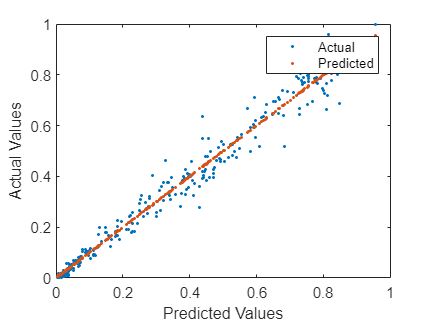

[trainedModel1, validationRMSE1, RMSE1] = SVM_train(datos, 'linear', [], 'auto', 5);

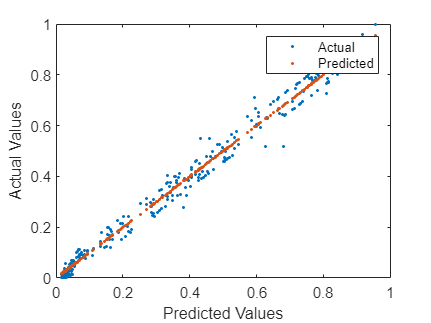

%validationRMSE1
[trainedModel2, validationRMSE2, RMSE2] = SVM_train(datos, 'polynomial', 2, 'auto', 5);

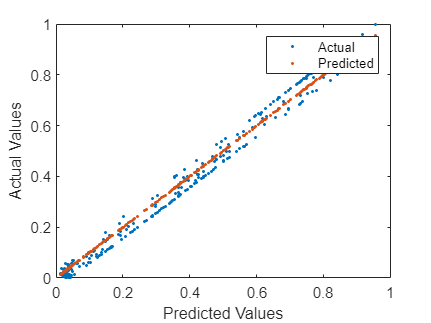

%validationRMSE2
[trainedModel3, validationRMSE3, RMSE3] = SVM_train(datos, 'gaussian', [], 0.9, 5);

%validationRMSE3

Visuaización consolidada por MSE

modelos = ["Lineal"; "Polinomial"; "Gausiano"];

mse_lineal = [RMSE1, RMSE2, RMSE3];


resultados = table(modelos, mse_lineal');
resultados.Properties.VariableNames = {'Modelos', 'MSE'};

disp(resultados);

      Modelos         MSE   
    ____________    ________

    "Lineal"        0.044299
    "Polinomial"    0.035088
    "Gausiano"      0.032823

